## **Read image**

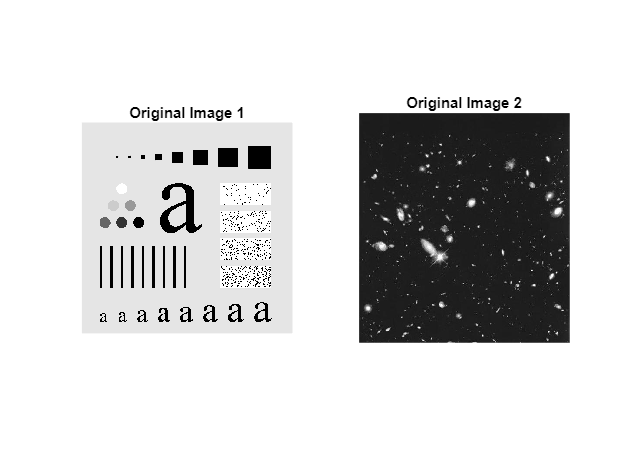

i1 = imread('Fig0333(a)(test_pattern_blurring_orig).tif');
i2 = imread('Fig0334(a)(hubble-original).tif');
figure;
subplot(1, 2, 1), imshow(i1), title('Original Image 1');
subplot(1, 2, 2), imshow(i2), title('Original Image 2');

## **Define Weighted Average Filters (Low-Pass Filter)**

**3x3 weighted average filter**

w3 = [1 2 1; 2 4 2; 1 2 1] / 16;

**5x5 weighted average filter**

w5 = [1 4 6 4 1; 4 16 24 16 4; 6 24 36 24 6; 4 16 24 16 4; 1 4 6 4 1] / 256;

**7x7 weighted average filter**

w7 = [1 6 15 20 15 6 1; 6 36 90 120 90 36 6; 15 90 225 300 225 90 15; 
      20 120 300 400 300 120 20; 15 90 225 300 225 90 15; 
      6 36 90 120 90 36 6; 1 6 15 20 15 6 1] / 784;

disp('Weighted Average LPF Filters Defined');

Weighted Average LPF Filters Defined


**Apply 3x3 Weighted Filter**

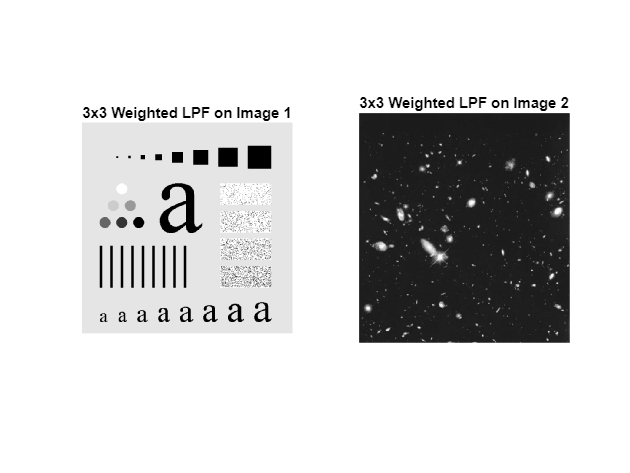

imgw3_1 = imfilter(i1, w3, 'replicate');
imgw3_2 = imfilter(i2, w3, 'replicate');
figure;
subplot(1, 2, 1), imshow(imgw3_1), title('3x3 Weighted LPF on Image 1');
subplot(1, 2, 2), imshow(imgw3_2), title('3x3 Weighted LPF on Image 2');

**Apply 5x5 Weighted Filter**

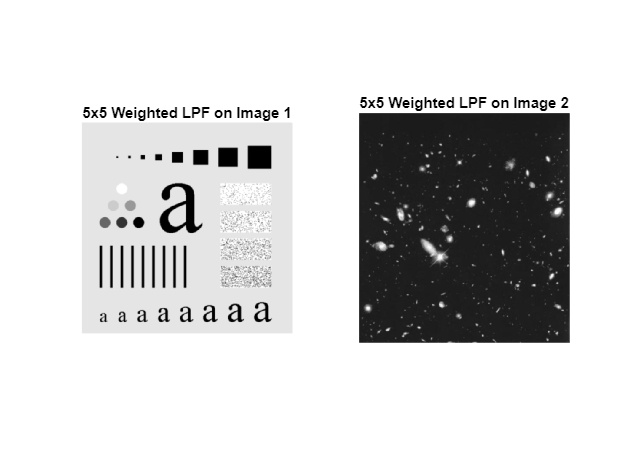

imgw5_1 = imfilter(i1, w5, 'replicate');
imgw5_2 = imfilter(i2, w5, 'replicate');
figure;
subplot(1, 2, 1), imshow(imgw5_1), title('5x5 Weighted LPF on Image 1');
subplot(1, 2, 2), imshow(imgw5_2), title('5x5 Weighted LPF on Image 2');

**Apply 7x7 Weighted Filter**

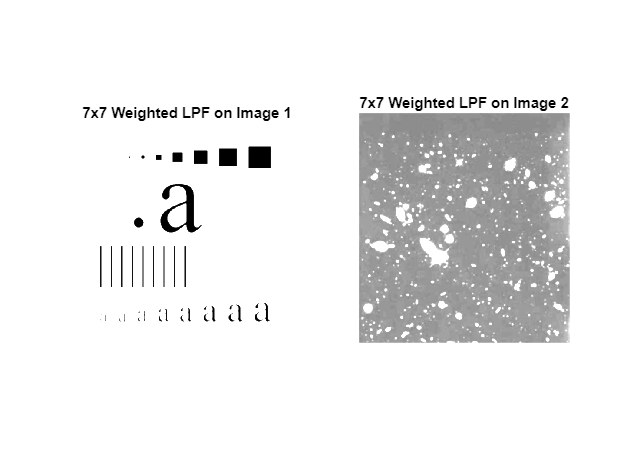

imgw7_1 = imfilter(i1, w7, 'replicate');
imgw7_2 = imfilter(i2, w7, 'replicate');
figure;
subplot(1, 2, 1), imshow(imgw7_1), title('7x7 Weighted LPF on Image 1');
subplot(1, 2, 2), imshow(imgw7_2), title('7x7 Weighted LPF on Image 2');

**Display results**

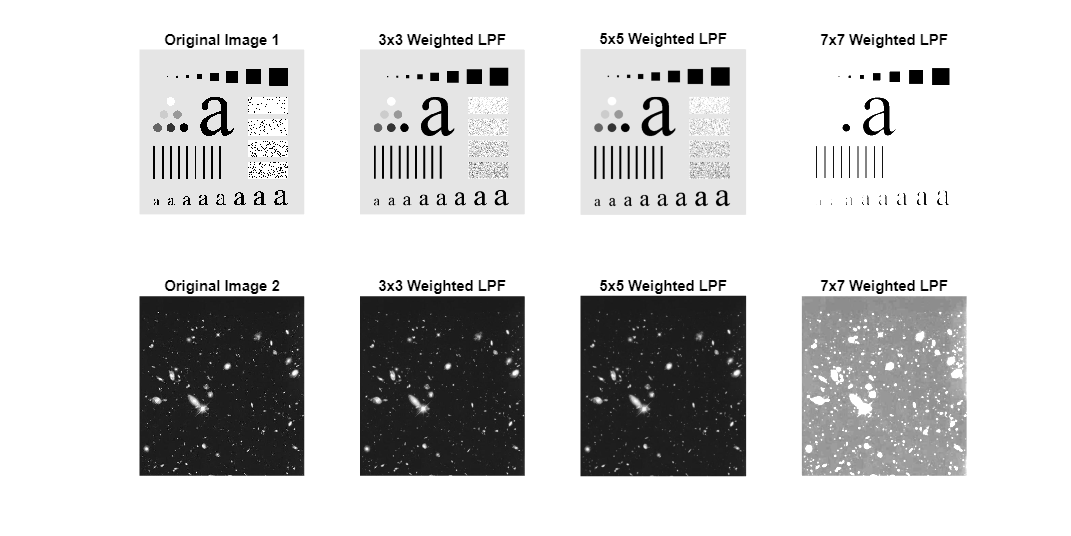

figure('Position', [100, 100, 1400, 700]);
subplot(2, 4, 1), imshow(i1), title('Original Image 1');
subplot(2, 4, 2), imshow(imgw3_1), title('3x3 Weighted LPF');
subplot(2, 4, 3), imshow(imgw5_1), title('5x5 Weighted LPF');
subplot(2, 4, 4), imshow(imgw7_1), title('7x7 Weighted LPF');
subplot(2, 4, 5), imshow(i2), title('Original Image 2');
subplot(2, 4, 6), imshow(imgw3_2), title('3x3 Weighted LPF');
subplot(2, 4, 7), imshow(imgw5_2), title('5x5 Weighted LPF');
subplot(2, 4, 8), imshow(imgw7_2), title('7x7 Weighted LPF');